# Variational mode decomposition (VMD) of monthly runoff

Thanks Dragomiretskiy and Zosso (2014) for providing VMD implementation!

- Clear the workspace.

- Read monthly runoff.

- Set decomposition parameters and save path.

- Tune decomposition level K.

- Decompose the entire set.

- Decompose the training set.

- Decompose the training-development set.

- Decompose the appended set.

## 1 Clear the workspace

clear;
close all;
clc;

## 2 Read monthly runoff

data_path='../time_series/';
station='Huaxian'; %'Huaxian', 'Xianyang' or 'Zhangjiashan'
switch station
    case 'Huaxian'
        save_path = '../Huaxian_vmd/data/';
        data = xlsread([data_path,'HuaxianRunoff1951-2018(1953-2018).xlsx'],1,'B26:B817');%full=792samples
    
    case 'Xianyang'
        save_path = '../Xianyang_vmd/data/';
        data = xlsread([data_path,'XianyangRunoff1951-2018(1953-2018).xlsx'],1,'B26:B817');%full=792samples
        
    case 'Zhangjiashan'
        save_path = '../Zhangjiashan_vmd/data/';
        data = xlsread([data_path,'ZhangJiaShanRunoff1953-2018(1953-2018).xlsx'],1,'B2:B793');%full=792samples
end

## 3 Set decomposition parameters and save path

if exist([save_path,'vmd-test'])==0
    mkdir([save_path,'vmd-test']);
end

% % some sample parameters for VMD  
addpath('./VMD');
alpha = 2000;       % moderate bandwidth constraint    
tau = 0;            % noise-tolerance (no strict fidelity enforcement) 
DC = 0;             % no DC part imposed
init = 1;           % initialize omegas uniformly  
tol = 1e-9;         % the convergence tolerance              

## 4 Tune decomposition level K.

The number of modes, i.e., decomposition level, should be tested based on the training set. 

Varies K from K=2 and observe the center frequency aliasing phenomenon of the last imf, e.g., 

center frequency alising phenomenon of imf9 is first observed when K=9, then the optimal K is set to 8.

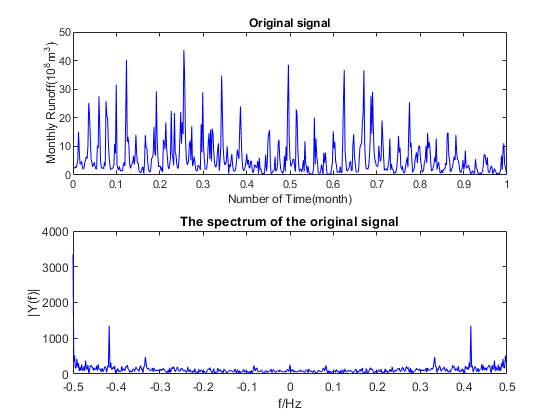

K=9;% number of modes, i.e., decomposition level. Should be tested based on training set
train_len = 552;
train = data(1:train_len);%train
[imf, u_hat, omega] = VMD(train', alpha, tau, K, DC, init, tol);
imf = imf';
T = length(train);
fs = 1/T;
t = (1:T)/T;
freqs = t-0.5-1/T;

figure
subplot(211);
plot(t,train,'b');
set(gca,'FontSize',8,'XLim',[0 t(end)]);
title('Original signal');
xlabel('Number of Time(month)');
ylabel('Monthly Runoff(10^8m^3)');
subplot(212);
% [Yf, f] = FFTAnalysis(x, Ts);
plot(freqs,abs(fft(train)),'b');
title('The spectrum of the original signal');
xlabel('f/Hz');
ylabel('|Y(f)|');

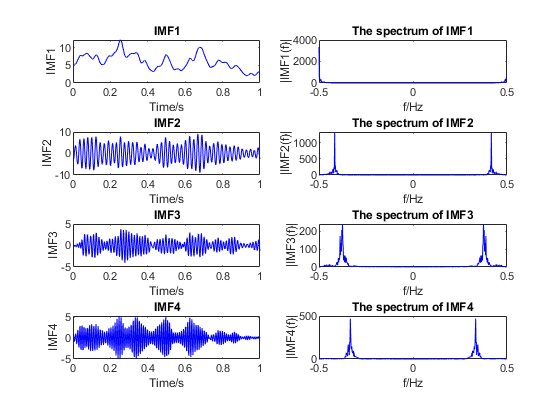

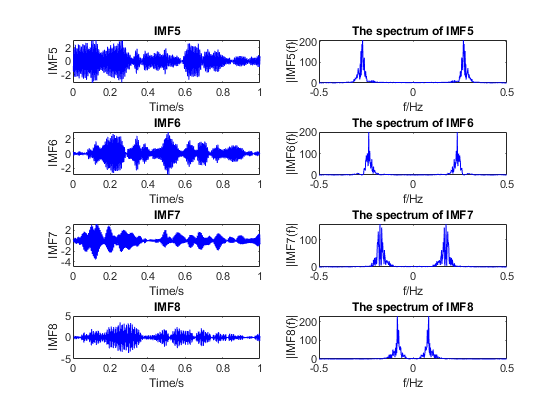

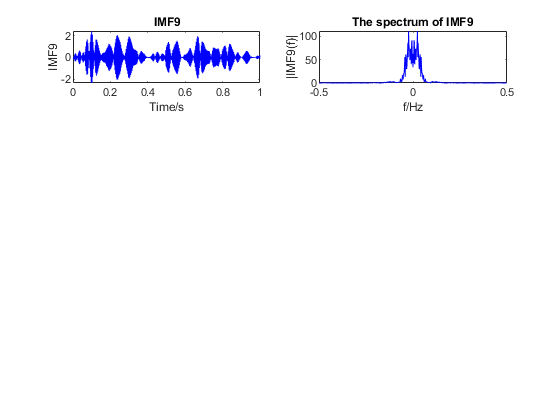


for k1 = 0:4:K-1
    figure
    for k2 = 1:min(4,K-k1)
        subplot(4,2,2*k2-1);
        plot(t,imf(:,k1+k2),'b');
        set(gca,'FontSize',8,'XLim',[0 t(end)]);
        title(sprintf('IMF%d', k1+k2));
        xlabel('Time/s');
        ylabel(sprintf('IMF%d', k1+k2));
        
        subplot(4,2,2*k2);
%         [yf, f] = FFTAnalysis(imf(k1+k2,:), fs);        
        plot(freqs, abs(fft(imf(:,k1+k2))),'b');
        title(sprintf('The spectrum of IMF%d', k1+k2));
        xlabel('f/Hz');
        ylabel(sprintf('|IMF%d(f)|',k1+k2));
    end
end


figure
subplot(4,2,2*k2-1);
plot(t,imf(:,k1+k2),'b');
set(gca,'FontSize',8,'XLim',[0 t(end)]);
title(sprintf('IMF%d', k1+k2));
xlabel('Time/s');
ylabel(sprintf('IMF%d', k1+k2));
        
subplot(4,2,2*k2)
%[yf, f] = FFTAnalysis(imf(k1+k2,:), fs);        
plot(freqs, abs(fft(imf(:,k1+k2))),'b');
title(sprintf('The spectrum of IMF%d', k1+k2));
xlabel('f/Hz');
ylabel(sprintf('|IMF%d(f)|',k1+k2));
savefig([station,'_vmd_k',num2str(K),'_a',num2str(alpha),'.fig']);



switch station
    case 'Huaxian'
        K=8;
    case 'Xianyang'
        K=8;
    case 'Zhangjiashan'
        K=7;
end

columns = {};
for i=1:(K+1)
    if i==1
        columns{i}='ORIG';
    else
        columns{i}=['IMF',num2str(i-1)];
    end
end

## 5 Decompose the entire set.

[imf, u_hat, omega] = VMD(data', alpha, tau, K, DC, init, tol);
imf = imf';
signals=[data,imf];
decompositions = array2table(signals, 'VariableNames', columns);
file_name=['VMD_FULL.csv'];
writetable(decompositions, [save_path,file_name])

## 6 Decompose the training set.

[imf, u_hat, omega] = VMD(train', alpha, tau, K, DC, init, tol);
imf = imf';
train_signals=[train,imf];
train_decompositions = array2table(train_signals, 'VariableNames', columns);
file_name=['VMD_TRAIN.csv'];
% file_name=strcat('VMD_TRAIN_alpha',num2str(alpha),'.csv');
writetable(train_decompositions, [save_path,file_name]);

## 7 Decompose the training-development set

train_dev_len = 672;
train_dev = data(1:train_dev_len);%training-development set
%%----- Run actual VMD code
[imf, u_hat, omega] = VMD(train_dev', alpha, tau, K, DC, init, tol);
imf = imf';
%%----- Save training-development decomposition
train_dev_signals=[train_dev,imf];
train_dev_decompositions = array2table(train_dev_signals, 'VariableNames', columns);
file_name=['VMD_TRAINDEV.csv'];
writetable(train_dev_decompositions, [save_path,file_name]);

save(['../results_analysis/results/',station,'-vmd.mat']);

## 8 Decompose the appended set.

for i=1:240+20  %1:240
    appended = data(1:(train_len-20+i));
    % run vmd
    [imf, u_hat, omega] = VMD(appended', alpha, tau, K, DC, init, tol);
    imf = imf';
    %save vmd
    appended_signals=[appended,imf];
    appended_decompositions = array2table(appended_signals, 'VariableNames', columns);
    a2=[save_path,'vmd-test/vmd_appended_test'];
    b2=num2str(train_len-20+i);
    c2='.csv';
    abc2=[a2,b2,c2];
    writetable(appended_decompositions, abc2)
end